clear

load('input.mat')

[lambda, llh] = hmmEM(data, opt.lambda, opt.maxIter, opt.tol);

Smoother took 1.586617 seconds on interation 1.00 
Baum Welch took 5.060432 seconds on interation 1.00 
Smoother took 1.534563 seconds on interation 2.00 
Baum Welch took 4.082338 seconds on interation 2.00 
Smoother took 1.254252 seconds on interation 3.00 
Baum Welch took 3.637411 seconds on interation 3.00 
Smoother took 1.393394 seconds on interation 4.00 
Baum Welch took 4.026129 seconds on interation 4.00 
Smoother took 1.410132 seconds on interation 5.00 
Baum Welch took 3.746276 seconds on interation 5.00 
Smoother took 1.338174 seconds on interation 6.00 
Baum Welch took 3.778849 seconds on interation 6.00 
Smoother took 1.374206 seconds on interation 7.00 
Baum Welch took 3.882215 seconds on interation 7.00 
Smoother took 1.284275 seconds on interation 8.00 
Baum Welch took 3.589891 seconds on interation 8.00 
Smoother took 1.253516 seconds on interation 9.00 
Baum Welch took 3.680044 seconds on interation 9.00 
Smoother took 1.232759 seconds on interation 10.00 


[gamma_t, epsilon, alpha, beta, c] = hmmSmoother_(data, lambda);
[viterbi, logP] = hmmViterbi_(data,lambda);

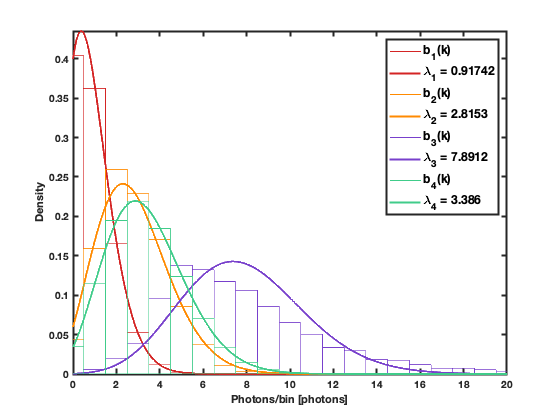

colors = [0.83 0.14 0.14
             1.00 0.54 0.00
             0.47 0.25 0.80
             0.25 0.80 0.54];
         
%plot distributions
figure
LegHandles = [];
LegText = {};
hold on
x_max = 50;
res = 0.01;
d = 0:1:x_max-1;
%continuous version of poisson, for plotting only
k = 0:res:x_max-1;
poiss_cont = @(lam)(lam.^k.*exp(-lam)./gamma(k+1));

for i = 1:size(lambda.B,1)
    %plot bar
    LegHandles(end+1) = bar(d,lambda.B(i,1:x_max),'hist');
    set(LegHandles(end),'FaceColor','none','EdgeColor',colors(i,:),...
        'LineStyle','-', 'LineWidth',1);
    LegText{end+1} = ['b_',num2str(i),'(k)'];
    
    %calculate and plot fit
    lam_temp = sum((0:1:size(lambda.B,2)-1).*lambda.B(i,:)); %mean definition of poisson
    LegHandles(end+1) = plot(k,poiss_cont(lam_temp),'Color',colors(i,:));
    LegText{end+1} = ['\lambda_',num2str(i),' = ',num2str(lam_temp)];
end

xlabel('Photons/bin [photons]');
ylabel('Density')
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 12, 'Location', 'northeast');
axis tight
set(gca,'xlim',[0,20])